# Introduction to Fluid Dynamics

[⇦ Overview](matlab:open('./Overview.m'))

Fluid Dynamics is the branch of mechanics that study liquid and gases in motion. What makes fluid flow? What are the forces in action? Will it fly?

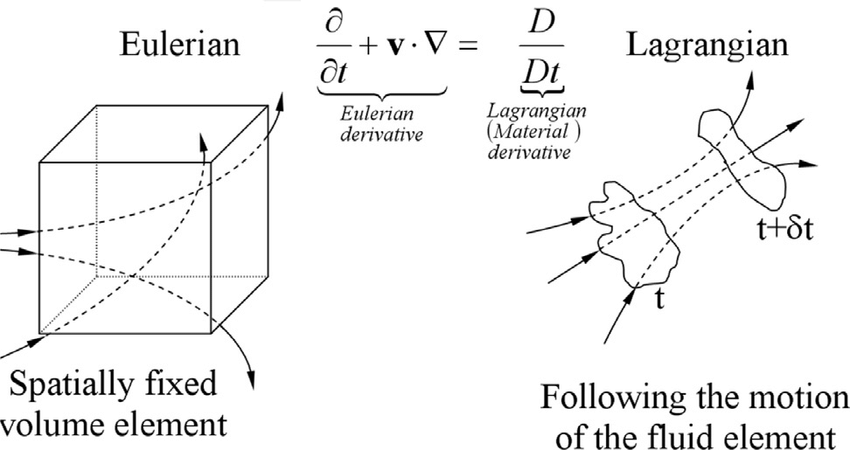

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

## Notation and Mathematical concept

Before to get started on this introduction to fluid dynamics, we should define some notation that will be in use for the rest of this fluid dynamics module. The preriquisite for this course incude multivariable functon analysis and their derivative, vector math.

Vector will be denoted used bold font, for example the velocit vector ${\bf\it u} = $

$\frac{\partial f\;}{\partial x}=\lim_{h\to 0} \frac{\;f\left(x+h,y\right)-f\left(x,y\right)}{h}$  and  $\frac{\partial f\;}{\partial u}=\lim_{h\to 0} \frac{\;f\left(x,y+h\right)-f\left(x,y\right)}{h}$.

The gradient operator nabla is defined as followed:

$\nabla_{1D} \equiv \frac{\;\partial \;}{\partial x\;}$;  $\nabla_{2D} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial \;}{\partial x\;}\\
\frac{\;\partial \;}{\partial y}
\end{array}\right\rbrack }_{\textrm{carthesian}} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial }{\partial r}\\
\frac{\;1}{r}\frac{\;\partial \;}{\partial \theta \;}
\end{array}\right\rbrack }_{\textrm{polar}}$; $\nabla_{3D} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial \;}{\partial x\;}\\
\frac{\;\partial \;}{\partial y}\\
\frac{\;\partial }{\partial z}
\end{array}\right\rbrack }_{\textrm{carthesian}} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial }{\partial r}\\
\frac{\;1}{r}\frac{\;\partial \;}{\partial \theta \;}\\
\frac{\;\partial \;}{\partial z}
\end{array}\right\rbrack }_{\textrm{cylindrical}} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial \;}{\partial r}\\
\frac{\;1}{r}\frac{\;\partial \;}{\partial \theta \;}\\
\frac{\;1}{\textrm{rsin}\left(\theta \;\right)}\frac{\;\partial \;}{\partial \varphi \;\;}
\end{array}\right\rbrack }_{\textrm{spherical}} \;$

These expression represent the nable operator for one, two and three dimensional coordinates system in carthesian but also polar, cylindrical and spherical system.

Lastly, vector such as the velocity of position vector will be represented using bold font over arrow superscript.


$$\mathit{\mathbf{u}}=\left\lbrack \begin{array}{c}
u_x \\
u_y \\
u_z 
\end{array}\right\rbrack$$


The curl operator $\nabla\times{\bf F} = $

## Mathematical concept

Stoke's theorem: 

Gauss's divergence theorem: $\int\int\int$

## Classification of fluid flow

XXX Finish this definition and think of an example

also called fluid elements

A fluid parcels is an imaginary 

Condition are uniform in the fluid parcel

No specific size

**Motivating Example:**

## **Common physical quatity used in fluid dynamics**

**Mass conservation -> Rho**

**Momentum equation -> Rho*U**

**Velocity field -> Vorticity (local spinning of fluid element) -> Turbulence versus Laminar, and Irrotational Flow**

**Viscosity**

**Temperature -> Compressible flow, conservation of energy etc**

## **Two point of view on fluid flow**

### **The Lagrangian point of view**

With the Lagrangian point of view, the observer is specifying the fluid flow by following individual fluid parcels throw time. It is the same point of view that is generaly in classical solid mechanics. You might remember from your kinetmatic course that to characterize the motion of a solid in space, it often suffices to only track the motion associated to one of the point of this solid. The mathematical description of a flow using Lagrangian point of view is composed of many function such as ${\bf X}_{\bf x_0}(t)$, which tracks the position of a fluid parcel with respect to time. In this case, the subscript ${\bf x_0}$ identify the fluid parcel being observe by specifying its initial position.

**Motivating Example: Ocean Drift barge**

The Lagrangian Drifter Laboratory (LDL) [1] is a part of the National Ocenic and Atmospheric Administration (NOAA) that has been focusing for over 40 years in the deployment of a fleet of drifter in every oceans around the world. This array of now over 1,300 drifter provides crucial data for the climate analysis and forecasting, especially for the in-situ investigation of Atlantic hurricanes.

The following data has been gathered from the LDL global drifter database of 2022 Atlantic hurricanes [2]. To visualize the data select the platform code of one of the drifter that have been observed in 2022 around the coast of the United States. The possible set of platform available for visualization has been reduced for optimal results.

% Select a drifter
Platform = 4201644;
plotDrifter(Platform)

Lagrangian experimentation are advantageous because they provide in-situ data. For example, the drifter data gathered the longitude and lattitude of the drifter at different point in time. Considering that the drifter is moving along with the oceanic surface current, we can find the velocity of the current by taking the derivative of the distance travelled with respect to time:

plotVelocity(Platform)

  **Reflect**. How convenient is the Lagrangian point of view?

If you have not done so already, take a look at the drifter identified by platform 4402877. In April 2022, this drifter begin its journey from the Gulf of Mexico to the Atlantic Ocean before to beach on the Atlantic coast of Florida in early May 2022. Further experimentation using this drifter would require retrieval and re-launch in the ocean. 

### The Eulerian point of view

Unlike the Lagrangian point of view, the Eulerian point of view does not rely on following the fluid particle. In place, it observe the physical quantity at a location in space. In most Eulerian observation, the point of spatial observation point are often fixed. The fluid flow is mathematically described uising field function such as ${\bf u}({\bf x}, t)$ where ${\bf x}
$ refer to a physical point in space.

**Motivating Example: Ocean Buoy**

Bouy = 44033;
plotBouy(Bouy)



## Link in between Eulerian and Lagrangian

The laws of physics apply the the particle not the grid and because the Eulerian 

% Step 1: define an unsteady 2D Eulerian flow
% Step 2: track a particle


## Pathline, Streakline, Streamline

% On the same 2D Eulerian flow
% Define and plot a pathline, which was done in the previous step
% Define and plot a streakline, by asking the student to click on a point
% Define and plot the streamline and plot it, path of massless particle

% Show what happen if the flow is steady
% Show what happen if the flow is uniform
% Show what happen if the flow is steady and uniform

## Material derivative

 **Reflect**. The second law of physics tell us $m\frac{\;\partial \mathit{\mathbf{u}}}{\partial t}=\mathit{\mathbf{F}}$

A    Phi(x,t)

B    Phi(x+u*dt, t+dt)

% syms Phi(x,t) u dx dt
% 
% dPhidt = limit( ( Phi(x+u*dt, t+dt) - Phi(x,t) )/dt, dt, 0 )



$$\frac{D\phi \;}{\textrm{Dt}}=\frac{\;\partial \phi \;}{\partial t}+\mathit{\mathbf{u}}\cdot \nabla \phi \;$$


% [graduxx, graduxy] = gradient(ux, 0.1);
% [graduyx, graduyy] = gradient(uy, 0.1);
% Ax = 0.0 + ux.*graduxx + uy.*graduxy;
% Ay = 0.0 + ux.*graduyx + uy.*graduyy;
% A  = sqrt(Ax.^2+Ay.^2);
% contourf(xg, yg, A , 256, 'LineColor', 'none')
% hold on
% quiver(xg, yg, Ax, Ay, 'Color', 'w')
% xlim([0 1])
% ylim([0 1])
% xlabel("x-location")
% ylabel("y-location")
% title("Total derivative of velocity")
% hold off

 **Reflect**.This acceleration is the acceleration felt by the particle of fluid in this field of velocity. Newton's law $m\vec{a} =\sum \vec{\;F_{\textrm{ext}\;} }$

Physical properties of the system such as temperature, mass, density, or really anything is hold on the fluid particle wether than the grid.

## Reynolds Transport Theorem

So far we discussed how to describe the motion of the fluid particle


$$\int(\nabla\cdot {\bf F})dV=\int ({\bf F}\cdot{\bf n})dS$$


1 - Derive the Reynolds transport therorem

2 - Ask to apply the theorem to mass -> conservation of mass

3 - Conservation of energy?

% 

## References

[1] The Lagrangian Drifter Laboratory [website](https://gdp.ucsd.edu/ldl/)

[2] Global Drifter Program Atlantic Hurricane 2022 [Data](https://drifterdata.ucsd.edu/erddap/tabledap/GDP_AtlanticHurricane2022.html)

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

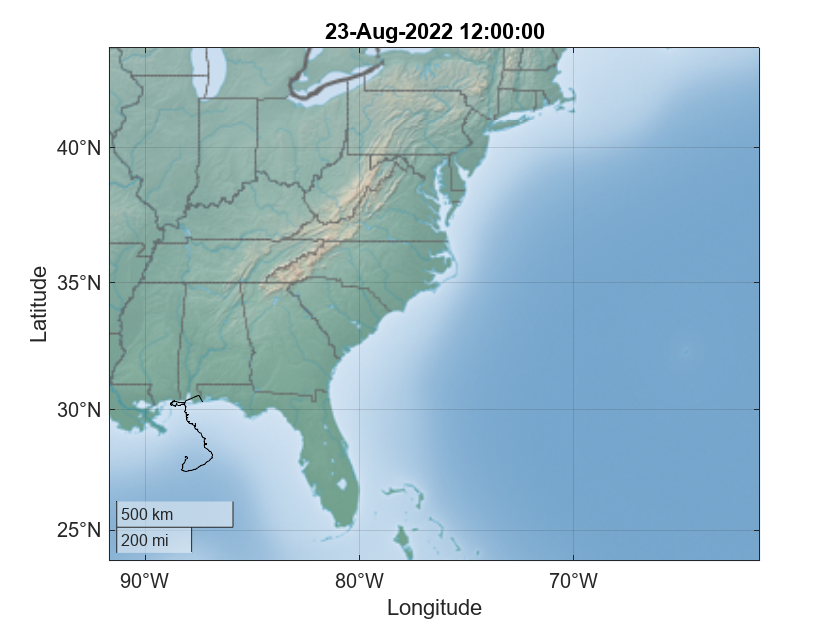

function plotDrifter(platform)
    
    load drifter.mat
   
    drifter = drifter( drifter.platform_code == platform, :);
    
    figure()
    geoaxes
    geolimits([23.7 43.5],[-91.6975 -61.3025])
    geobasemap colorterrain

    h = animatedline;
    for i = 1:size(drifter,1)

        addpoints(h, drifter.latitude(i), drifter.longitude(i))
        title(string(drifter.time(i)))
        if ( mod(i,5) == 0 )

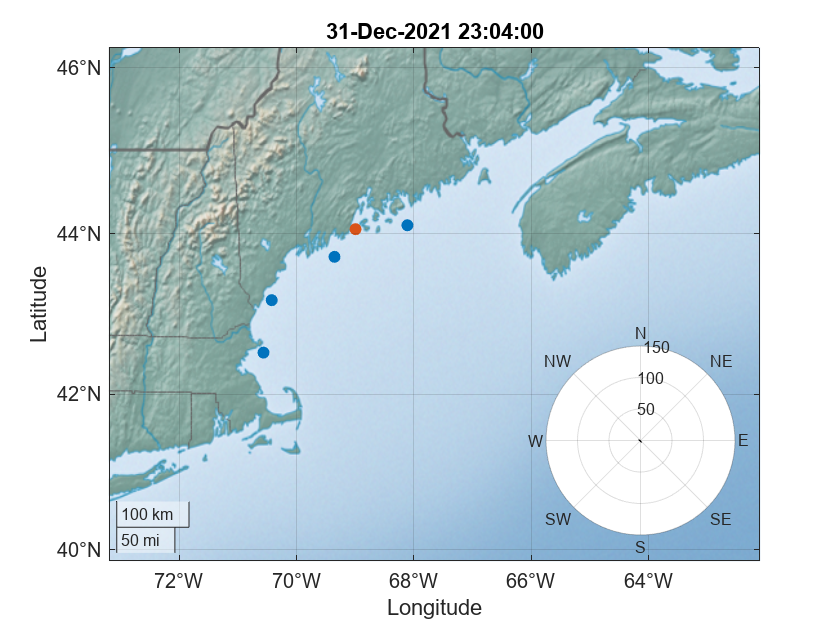

            drawnow
        end
    end
    hold off
end

function plotVelocity(platform)


    load drifter.mat

    drifter = drifter( drifter.platform_code == platform, :);
    drifter.d = zeros(size(drifter.longitude));
    for i = 2:length(drifter.d)
        drifter.d(i) = distance('gc', drifter.latitude(i), drifter.longitude(i), drifter.latitude(i-1), drifter.longitude(i-1), 'degrees');
    end
    drifter.d;
    drifter.d = cumsum(3951*drifter.d*pi/180);

    date  = drifter.time;
    dist  = drifter.d;
    date0 = linspace(date(1), date(end)-hours(24), 100);
    date1 = date0 + hours(24);
    dist0 = interp1(date, dist, date0);
    dist1 = interp1(date, dist, date1);
    v = (dist1-dist0)/24;
    
    figure()
    yyaxis left
    p = plot(date, dist, 'SeriesIndex', 1, 'LineStyle','-', 'LineWidth', 2);
    p.Parent.YColor = [0 0 0];
    xlabel("Date")
    ylabel("Distance travelled (mi)")
    yyaxis right
    p = plot(date1, v, 'SeriesIndex', 2, 'LineStyle', '-', 'LineWidth', 2);
    p.Parent.YColor = [0 0 0];
    legend('Distance travelled', 'Velocity', 'Location', 'east')
    ylabel("Velocity (mi/h)")

end

function plotBouy(Bouy)
    % Different color for the one that is selected
    f1 = figure();
    
    geop = geoscatter(NaN,NaN);
    hold on
    geolimits([41.6 45.7],[-72.7 -65.5])
    geobasemap colorterrain
    load BouysData.mat
    [Bouys, iBouys, ~] = unique(bouy.BOUY);
    % Plot all the bouy in SeriesIndex 1
    geop = geoscatter( bouy.LAT(iBouys), bouy.LON(iBouys), "filled", "SeriesIndex", 1);
    geolimits([39.9 46.2],[-73.2 -62.1])
    geobasemap colorterrain
    
    % Plot the bouy that is selected on SeriesIndex 2
    iSelect = iBouys( Bouys == Bouy);
    geoscatter( bouy.LAT(iSelect), bouy.LON(iSelect), "filled", "SeriesIndex", 2)
    
    
    figure
    pax = polarplot(NaN, NaN);
    pax.Parent.Parent = f1;
    pax.Parent.ThetaDir = "clockwise";
    pax.Parent.ThetaZeroLocation = "top";
    pax.Parent.ThetaTick = 0:45:360;
    pax.Parent.ThetaTickLabel = {'N', 'NE', 'E', 'SE', 'S', 'SW', 'W', 'NW'};
    pax.Parent.Position = [0.650 0.150 0.225 0.30];
    pax.Parent.RTick = [50 100 150];
    pax.Parent.RLim = [0 150];
    h = animatedline(pax.Parent, 'LineStyle', '-', 'LineWidth', 2);
    
    % Reduce dataset to the selected bouy data:
    bouy = bouy( bouy.BOUY == Bouy, :);
    bouy = sortrows(bouy, "DATE", "ascend");
    for i = 1:size(bouy,1)
        clearpoints(h)
        addpoints(h,  [0 bouy.DIR01(i)], bouy.SPD01(i)*[0 1])
        title(geop.Parent, string(bouy.DATE(i)))
        if ( mod(i,50) == 0 )
            drawnow
        end
    end
end

[⇦ Return to the navigation page](matlab: OpenOverview)